# **Stiffness matrix of rectangular QUAD finite elements**

We want to evaluate Stiffness matrix of a rectangular a x Gamma*a QUAD element

Shape function are:

gamma = sym('gamma');
a = sym('a');
N_1 = @aux1

N_1 = function_handle with value:
    @aux1



gamma = sym('gamma');
a = sym('a');
N_2 = @aux2

N_2 = function_handle with value:
    @aux2



gamma = sym('gamma');
a = sym('a');
N_3 = @aux3

N_3 = function_handle with value:
    @aux3



gamma = sym('gamma');
a = sym('a');
N_4 = @aux4

N_4 = function_handle with value:
    @aux4


For both planar strain and planar stress element the stress deformation matrix can be expressed in the form of

%syms C_1 C_2 C_3
%A = [C_1, C_2, sym(0); C_2, C_1, sym(0); sym(0), sym(0), C_3]

syms E nu 
A = [E/(1-nu^2), E*nu/(1-nu^2), sym(0); E*nu/(1-nu^2), E/(1-nu^2), sym(0); sym(0), sym(0), 0.5*E*(1-nu)/(1-nu^2)]

$$A = \left(\begin{array}{ccc} -\frac{\text{E}}{\nu^{2}-1} & -\frac{\text{E}\,\nu }{\nu^{2}-1} & 0\\ -\frac{\text{E}\,\nu }{\nu^{2}-1} & -\frac{\text{E}}{\nu^{2}-1} & 0\\ 0 & 0 & \frac{\text{E}\,\left(\nu -1\right)}{2\,\left(\nu^{2}-1\right)} \end{array}\right)$$

The stain displacement matrix can be computed analytically using diff

B = @aux13

B = function_handle with value:
    @aux13


The stiffness matrix integrand is then (h is the thickness):

h = sym('h');
kin = @aux16

kin = function_handle with value:
    @aux16



syms x y
kin(x,y)

Making a double integration one can get:

syms a gamma
KE = int(int(kin(x,y), x, -(a/2), a/2), y, -((a * gamma)/2), (a * gamma)/2)

$$KE = \begin{array}{l} \left(\begin{array}{cccccccc} -\frac{\sigma_{4}}{\sigma_{10}} & -\sigma_{2} & \sigma_{7} & -\sigma_{1} & \frac{\sigma_{4}}{\sigma_{9}} & \sigma_{2} & \sigma_{8} & \sigma_{1}\\ -\sigma_{2} & -\frac{\sigma_{3}}{\sigma_{10}} & \sigma_{1} & \sigma_{5} & \sigma_{2} & \frac{\sigma_{3}}{\sigma_{9}} & -\sigma_{1} & \sigma_{6}\\ \sigma_{7} & \sigma_{1} & -\frac{\sigma_{4}}{\sigma_{10}} & \sigma_{2} & \sigma_{8} & -\sigma_{1} & \frac{\sigma_{4}}{\sigma_{9}} & -\sigma_{2}\\ -\sigma_{1} & \sigma_{5} & \sigma_{2} & -\frac{\sigma_{3}}{\sigma_{10}} & \sigma_{1} & \sigma_{6} & -\sigma_{2} & \frac{\sigma_{3}}{\sigma_{9}}\\ \frac{\sigma_{4}}{\sigma_{9}} & \sigma_{2} & \sigma_{8} & \sigma_{1} & -\frac{\sigma_{4}}{\sigma_{10}} & -\sigma_{2} & \sigma_{7} & -\sigma_{1}\\ \sigma_{2} & \frac{\sigma_{3}}{\sigma_{9}} & -\sigma_{1} & \sigma_{6} & -\sigma_{2} & -\frac{\sigma_{3}}{\sigma_{10}} & \sigma_{1} & \sigma_{5}\\ \sigma_{8} & -\sigma_{1} & \frac{\sigma_{4}}{\sigma_{9}} & -\sigma_{2} & \sigma_{7} & \sigma_{1} & -\frac{\sigma_{4}}{\sigma_{10}} & \sigma_{2}\\ \sigma_{1} & \sigma_{6} & -\sigma_{2} & \frac{\sigma_{3}}{\sigma_{9}} & -\sigma_{1} & \sigma_{5} & \sigma_{2} & -\frac{\sigma_{3}}{\sigma_{10}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{E}\,h\,\left(3\,\nu -1\right)}{8\,\left(\nu^{2}-1\right)}\\ \sigma_{2}=\frac{\text{E}\,h}{8\,\left(\nu -1\right)}\\ \sigma_{3}=\text{E}\,h\,\left(\gamma^{2}-\gamma^{2}\,\nu +2\right)\\ \sigma_{4}=\text{E}\,h\,\left(2\,\gamma^{2}-\nu +1\right)\\ \sigma_{5}=-\frac{\text{E}\,h\,\left(\gamma^{2}\,\nu -\gamma^{2}+1\right)}{\sigma_{10}}\\ \sigma_{6}=\frac{\text{E}\,h\,\left(\gamma^{2}\,\nu -\gamma^{2}+4\right)}{\sigma_{9}}\\ \sigma_{7}=\frac{\text{E}\,h\,\left(4\,\gamma^{2}+\nu -1\right)}{\sigma_{9}}\\ \sigma_{8}=-\frac{\text{E}\,h\,\left(\gamma^{2}+\nu -1\right)}{\sigma_{10}}\\ \sigma_{9}=12\,\gamma \,\left(\nu^{2}-1\right)\\ \sigma_{10}=6\,\gamma \,\left(\nu^{2}-1\right) \end{array}$$

Whose eigenvalues are:

eig(KE)

$$ans = \begin{array}{l} \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{2\,\text{E}\,h\,\gamma^{2}+\text{E}\,h-\text{E}\,h\,\nu }{\sigma_{3}}\\ \frac{\text{E}\,h\,\gamma^{2}+\text{E}\,h}{2\,\gamma +2\,\gamma \,\nu }\\ \frac{2\,\text{E}\,h+\sigma_{2}-\text{E}\,\gamma^{2}\,h\,\nu }{\sigma_{3}}\\ -\frac{\text{E}\,h-\sigma_{1}+\sigma_{2}}{\sigma_{4}}\\ -\frac{\text{E}\,h+\sigma_{1}+\sigma_{2}}{\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=72\,\text{E}\,h\,\sqrt{\frac{\gamma^{4}}{5184}+\frac{\gamma^{2}\,\nu^{2}}{1296}-\frac{\gamma^{2}}{2592}+\frac{1}{5184}}\\ \sigma_{2}=\text{E}\,\gamma^{2}\,h\\ \sigma_{3}=6\,\gamma -6\,\gamma \,\nu^{2}\\ \sigma_{4}=2\,\gamma \,\left(\nu -1\right)\,\left(\nu +1\right) \end{array}$$

One can note that stiffness matrix terms do not depend on the element size a, quite surisingly.

The bigger the element is the bigger is the integration domain and the smaller is the deformation energy. The two effect compensate exactly.

## Substitution with 1x1 quad (for topology optimization)

a=double(subs(a,1))

a = 1

gamma=double(subs(gamma,1))

gamma = 1

E=double(subs(E,1));h=double(subs(h,1));

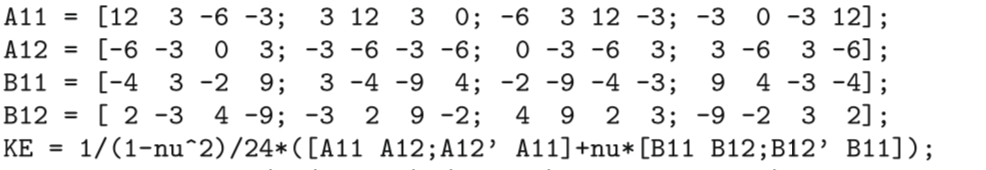

KE =  int(int(kin(x,y), x, -(a/2), a/2), y, -((a * gamma)/2), (a * gamma)/2)

$$KE = \begin{array}{l} \left(\begin{array}{cccccccc} \frac{\sigma_{3}}{\sigma_{7}} & -\sigma_{2} & \sigma_{4} & -\sigma_{1} & -\frac{\sigma_{3}}{\sigma_{6}} & \sigma_{2} & \sigma_{5} & \sigma_{1}\\ -\sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{1} & \sigma_{5} & \sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{1} & \sigma_{4}\\ \sigma_{4} & \sigma_{1} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{2} & \sigma_{5} & -\sigma_{1} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{2}\\ -\sigma_{1} & \sigma_{5} & \sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{1} & \sigma_{4} & -\sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}}\\ -\frac{\sigma_{3}}{\sigma_{6}} & \sigma_{2} & \sigma_{5} & \sigma_{1} & \frac{\sigma_{3}}{\sigma_{7}} & -\sigma_{2} & \sigma_{4} & -\sigma_{1}\\ \sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{1} & \sigma_{4} & -\sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{1} & \sigma_{5}\\ \sigma_{5} & -\sigma_{1} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{2} & \sigma_{4} & \sigma_{1} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{2}\\ \sigma_{1} & \sigma_{4} & -\sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{1} & \sigma_{5} & \sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{E}\,\left(3\,\nu -1\right)}{8\,\left(\nu^{2}-1\right)}\\ \sigma_{2}=\frac{\text{E}}{8\,\left(\nu -1\right)}\\ \sigma_{3}=\text{E}\,\left(\nu -3\right)\\ \sigma_{4}=\frac{\text{E}\,\left(\nu +3\right)}{\sigma_{6}}\\ \sigma_{5}=-\frac{\text{E}\,\nu }{\sigma_{7}}\\ \sigma_{6}=12\,\left(\nu^{2}-1\right)\\ \sigma_{7}=6\,\left(\nu^{2}-1\right) \end{array}$$

check and simplify !!

## Local Functions

function returnValue = aux1(x, y)
a = evalin('base', 'a');
gamma = evalin('base', 'gamma');

returnValue = 1/4 * (1 - (2 * x)/a) * (1 - (2 * y)/(a * gamma));
end

function returnValue = aux2(x, y)
a = evalin('base', 'a');
gamma = evalin('base', 'gamma');

returnValue = 1/4 * (1 + (2 * x)/a) * (1 - (2 * y)/(a * gamma));
end

function returnValue = aux3(x, y)
a = evalin('base', 'a');
gamma = evalin('base', 'gamma');

returnValue = 1/4 * (1 + (2 * x)/a) * (1 + (2 * y)/(a * gamma));
end

function returnValue = aux4(x, y)
a = evalin('base', 'a');
gamma = evalin('base', 'gamma');

returnValue = 1/4 * (1 - (2 * x)/a) * (1 + (2 * y)/(a * gamma));
end

function returnValue = aux13(x, y)
N_4 = evalin('base', 'N_4');
N_3 = evalin('base', 'N_3');
N_1 = evalin('base', 'N_1');
N_2 = evalin('base', 'N_2');

returnValue = [diff(N_1(x,y), x), sym(0), diff(N_2(x,y), x), sym(0), diff(N_3(x,y), x), sym(0), diff(N_4(x,y), x), sym(0); sym(0), diff(N_1(x,y), y), sym(0), diff(N_2(x,y), y), sym(0), diff(N_3(x,y), y), sym(0), diff(N_4(x,y), y); diff(N_1(x,y), y), diff(N_1(x,y), x), diff(N_2(x,y), y), diff(N_2(x,y), x), diff(N_3(x,y), y), diff(N_3(x,y), x), diff(N_4(x,y), y), diff(N_4(x,y), x)];
end

function returnValue = aux16(x, y)
A = evalin('base', 'A');
h = evalin('base', 'h');
B = evalin('base', 'B');

returnValue = h * transpose(B(x,y)) * A * B(x,y);
end